class1 = 'TURMER';
class2 = 'LUSMEG';

reportFigDir = 'report/figures';

signals = {};

directoryPath = sprintf('samples/%s/syllables/%s',class1,"train");
fileList = dir(fullfile(directoryPath, '*.wav'));   
limit = numel(fileList);
for ii = 1:limit
    filePath = fullfile(directoryPath, fileList(ii).name);
    [signal,~] = audioread(filePath);
    signal = mono(signal);
    if numel(signal) < 2.4e4
        signals(size(signals,1)+1,:) = {signal};
    end
end

directoryPath = sprintf('samples/%s/syllables/%s',class2,"train");
fileList = dir(fullfile(directoryPath, '*.wav'));   
limit = numel(fileList);
for ii = 1:limit
    filePath = fullfile(directoryPath, fileList(ii).name);
    [signal,~] = audioread(filePath);
    signal = mono(signal);
    if numel(signal) < 2.4e4
        signals(size(signals,1)+1,:) = {signal};
    end
end

L = cellfun(@length,signals);
h = histogram(L);

morebins(h);
morebins(h)

xticks(0:2000:2.5e4)
xlabel('Syllable sample length')
ylabel('Frequency')
hold on
xline(14000, 'r--', 'LineWidth', 2);
hold off

[audio,fs] = audioread('samples/TROTRO/raw/XC818793.mp3');
audio = mono(audio);
audio = audio(1:3*fs);

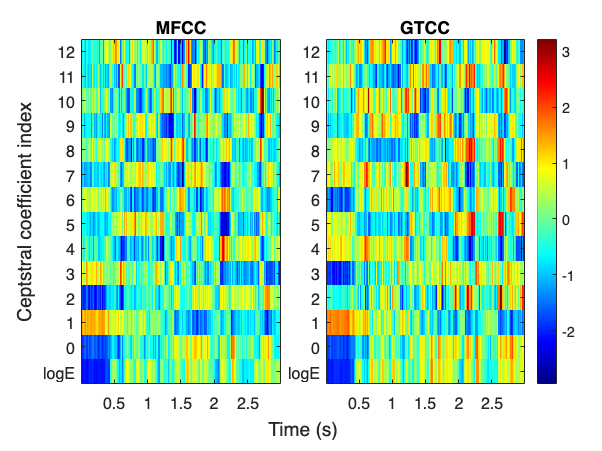

t = tiledlayout(1,2);
t.TileSpacing = "compact";

nexttile
mfcc(audio,fs)
colorbar off
ylabel ''
xlabel ''
title('MFCC')

nexttile
gtcc(audio,fs)
ylabel ''
xlabel ''
title('GTCC')

ylabel(t,'Ceptstral coefficient index')
xlabel(t,'Time (s)')

filtBank = gammatoneFilterBank([50, fs/2],64,fs);
audioOut = filtBank(audio);
mrcgFeatures = mrcg(audioOut,fs);

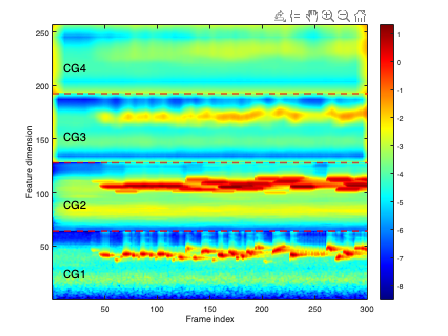

figure;
imagesc(mrcgFeatures);
colormap jet;
colorbar;
ylabel('Feature dimension');
xlabel('Frame index');
yline([64,64*2,64*3],'r--','LineWidth', 2);
% title(sprintf('%s MRCG',titleText));
text(ones(4,1)*10,25+(0:3)*64,{'CG1','CG2','CG3','CG4'},'FontSize',14)
set(gca,'YDir','normal');

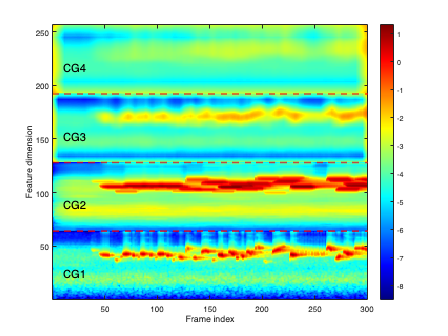

saveas(gcf,fullfile(reportFigDir,'mrcg_example.png'));

fs = 44100;
gfb = gammatoneFilterBank(SampleRate=fs);
fvtool(gfb)

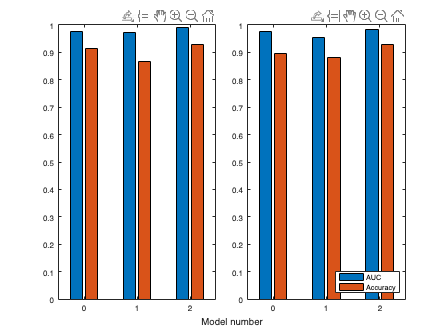

cnnGtccEvalData = zeros(3,2);
for i = 1:3
    cnnGtccEvalData(i,1) = cnnGtccEvalCell{i,2};
    cnnGtccEvalData(i,2) = cnnGtccEvalCell{i,3};
end

cnnMfccEvalData = zeros(3,2);
for i = 1:3
    cnnMfccEvalData(i,1) = cnnMfccEvalCell{i,2};
    cnnMfccEvalData(i,2) = cnnMfccEvalCell{i,3};
end

t = tiledlayout(1,2);
t.TileSpacing = "compact";

nexttile
bar(0:2,cnnMfccEvalData)
title('MFCC')

nexttile
bar(0:2,cnnGtccEvalData)
ylim([0 1])
title('GTCC')

legend({'AUC','Accuracy'},"Location","southeast")

xlabel(t, 'Model number')

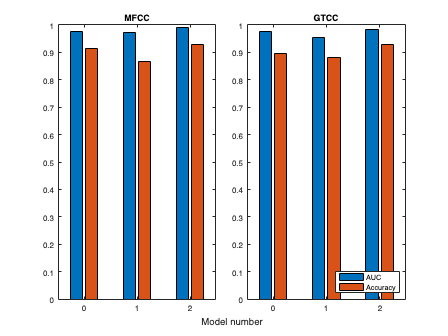

saveas(gcf,fullfile(reportFigDir,'hyp2_cnn_bar.png'));

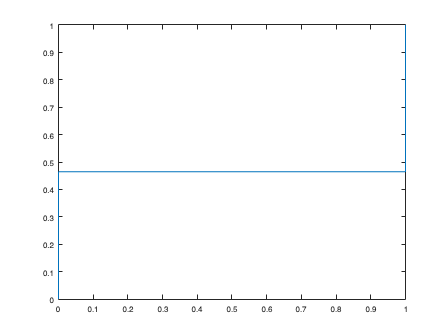

L = cellfun(@length,XTrainBase5);
histogram(L)
hold on
xline(14000,'r--','LineWidth',2)
hold off
xlabel('Sequence sample length')
ylabel('Frequency')

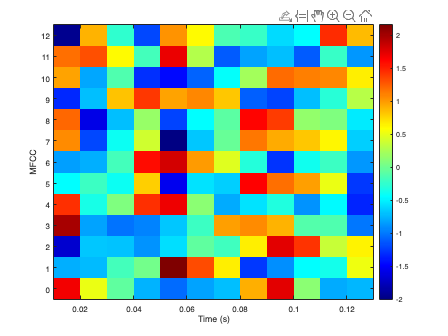

mfcc(XTrainBase5{7},fsTrain{7},'LogEnergy','ignore')

coeffs = mfcc(XTrainBase5{7},fsTrain{7},'LogEnergy','ignore');

numElements = 7;

% Initialize an empty cell array
coeffCellArray = cell(1, numElements);

% Populate the cell array with the desired strings
for i = 1:numElements
    coeffCellArray{i} = ['C', num2str(i+6)];
end

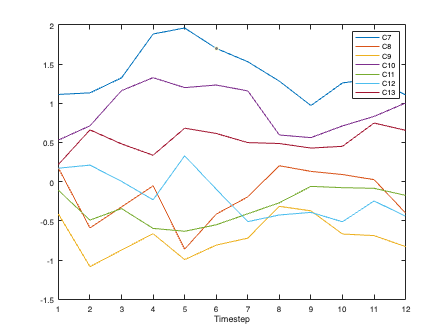

figure;
plot(coeffs(:,7:end))
xlim([1 12])
legend(coeffCellArray)
xlabel('Timestep')

modelIds = {
'SVM\_M\_L\_1',...
'SVM\_M\_R\_1',...
'SVM\_M\_L\_2',...
'SVM\_M\_R\_2',...
'SVM\_M\_L\_3',...
'SVM\_M\_R\_3',...
'SVM\_M\_L\_4',...
'SVM\_M\_R\_4',...
'SVM\_M\_L\_5',...
'SVM\_M\_R\_5',...
'SVM\_M\_L\_6',...
'SVM\_M\_R\_6',...
'SVM\_M\_L\_7',...
'SVM\_M\_R\_7',...
'SVM\_G\_L\_1',...
'SVM\_G\_R\_1',...
'SVM\_G\_L\_2',...
'SVM\_G\_R\_2',...
'SVM\_G\_L\_3',...
'SVM\_G\_R\_3',...
'SVM\_G\_L\_4',...
'SVM\_G\_R\_4',...
'CNN\_M\_1',...
'CNN\_G\_1',...
'CNN\_M\_2',...
'CNN\_G\_2',...
'CNN\_M\_3',...
'CNN\_G\_3',...
'RNN\_M\_1',...
'CRNN\_M\_1',...
'CRNN\_M\_2',...
'CNN\_C\_1',...
'RNN\_C\_1',...
'CRNN\_C\_1',
};

mfccSvmBar = zeros(length(mfccEvalCell),2);
for i = 1:2:length(mfccEvalCell)
    mfccSvmBar(i,:) = [mfccEvalCell{i+1,3:4}];
    mfccSvmBar(i+1,:) = [mfccEvalCell{i,3:4}];
end
gtccSvmBar = zeros(length(gtccEvalCell),2);
for i = 1:2:length(gtccEvalCell)
    gtccSvmBar(i,:) = [gtccEvalCell{i+1,3:4}];
    gtccSvmBar(i+1,:) = [gtccEvalCell{i,3:4}];
end
cnnBar = zeros(6,2);
for i = 1:2:6
    cnnBar(i,:) = [cnnMfccEvalCell{ceil(i/2),2:3}];
    cnnBar(i+1,:) = [cnnGtccEvalCell{ceil(i/2),2:3}];
end
rnnBar = zeros(3,2);
for i = 1:3
    rnnBar(i,:) = [rnnVEvalCell{i,2:3}];
end
rnnMrcgEvalCell = {
    1, 0.968, 0.889;
    2, 0.188, 0.283;
    3, 0.138, 0.205;
};
mrcgBar = zeros(3,2);
for i = 1:3
    mrcgBar(i,:) = [rnnMrcgEvalCell{i,2:3}];
end
allBars = [mfccSvmBar;gtccSvmBar;cnnBar;rnnBar;mrcgBar];

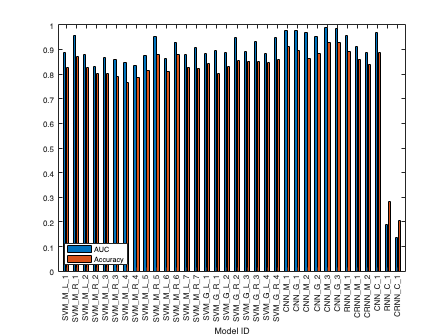

X = categorical(modelIds);
X = reordercats(X,modelIds);
bar(X,allBars)
xlabel('Model ID')
legend({'AUC','Accuracy'},"Location","southwest");
set(gca,'XTickLabelRotation', 90)

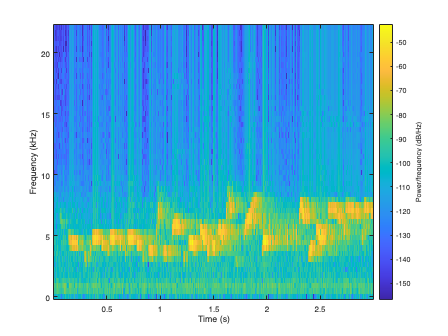

[audio,fs] = audioread('samples/TROTRO/raw/XC818793.mp3');
audio = mono(audio);
audio = audio(0.3*fs:3.3*fs);
spectrogram(audio,100,80,100,fs,'yaxis')

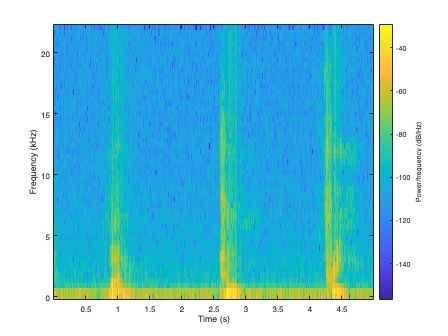

[haudio,hfs] = audioread('Counting-16-44p1-mono-15secs.wav');
haudio = mono(haudio);
haudio = haudio(1:5*fs);
spectrogram(haudio,100,80,100,fs,'yaxis')

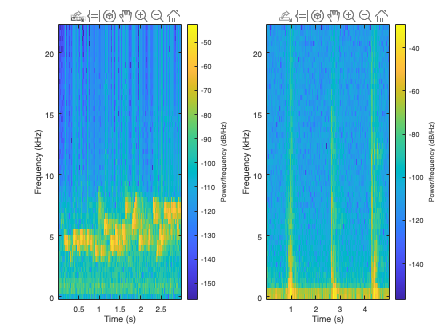

t = tiledlayout(1,2);

nexttile
spectrogram(audio,100,80,100,fs,'yaxis')
title('Eurasian wren birdsong')
% ylabel('')

nexttile
spectrogram(haudio,100,80,100,fs,'yaxis')
title('Human speech')

% ylabel('')

% ylabel(t,'Frequency (kHz)')